# 3.1. Кулоновское поле

#### [Закон Кулона](https://ru.wikipedia.org/wiki/Закон_Кулона)

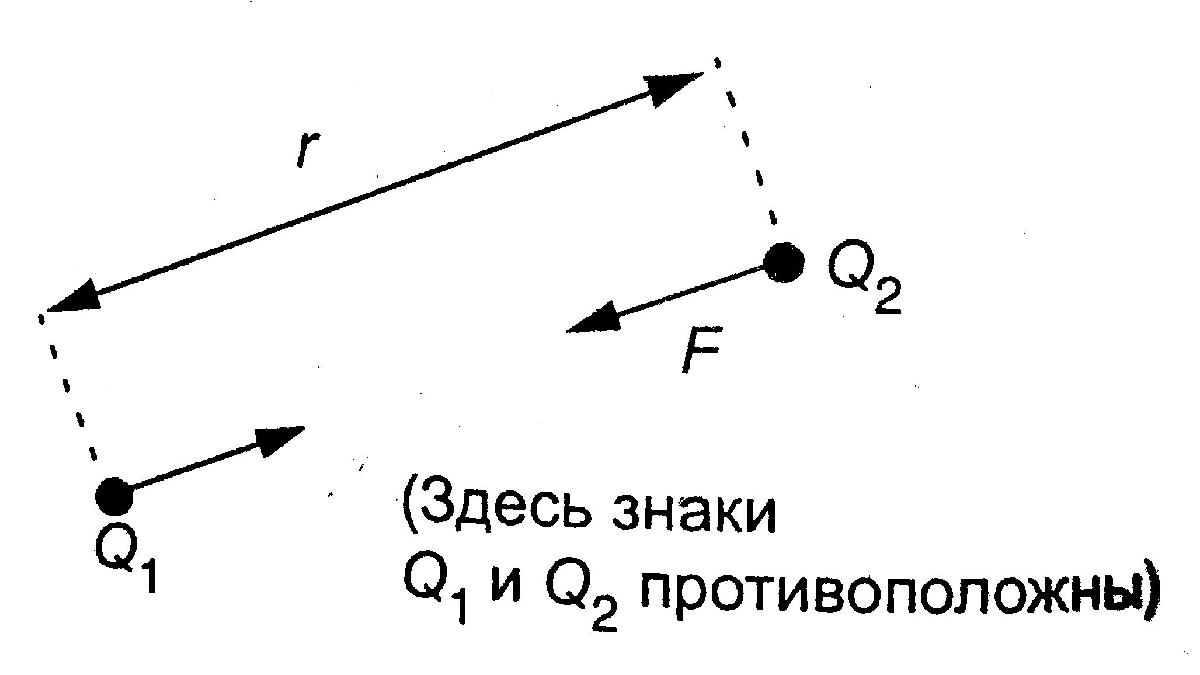

clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms F Q1 Q2 epsilon0 r
F==Q1*Q2/(4*pi*epsilon0*r^2)

$$ans = F=\frac{Q_{1}\,Q_{2}}{4\,\epsilon_{0}\,r^{2}\,\pi }$$

#### [Напряженность поля](https://ru.wikipedia.org/wiki/Напряжённость_электрического_поля) и [потенциал](https://ru.wikipedia.org/wiki/Электромагнитный_потенциал)


$$\mathit{\mathbf{E}}=\frac{\mathit{\mathbf{F}}}{Q}$$



$$\mathit{\mathbf{E}}=\frac{1}{4\;\pi \;\varepsilon_0 }\int \frac{\rho }{r^2 }\frac{\mathit{\mathbf{r}}}{r}\mathrm{dv}$$


syms E F Q epsilon0 rho(v) r v
E==F/Q==1/(4*pi*epsilon0)*int(rho/r^2,v)

$$ans(v) = \left(\text{E}=\frac{F}{Q}\right)=\frac{\int \frac{\rho \left(v\right)}{r^{2}}\mathrm{d}v}{4\,\epsilon_{0}\,\pi }$$

% v = объем
% F = сила, действующая на заряд Q в электрическом поле E


$$E=-\mathrm{grad}\;V$$


syms V
E==-grad(V)

$$ans = \text{E}=-\mathrm{grad}\left(V\right)$$

% gradV = grad(V) = ∇V


$$V_A -V_B =-\int_B^A \mathit{\mathbf{E}}\cdot \mathbf{dr}$$


syms r E(r) V_A V_B A B
V_A-V_B==-int(E,r,B,A)

$$ans = V_{A}-V_{B}=-\int_{B}^{A}\text{E}\left(r\right)\mathrm{d}r$$

V==1/(4*pi*epsilon0)*int(rho/r,v)

$$ans(v) = V=\frac{\int \frac{\rho \left(v\right)}{r}\mathrm{d}v}{4\,\epsilon_{0}\,\pi }$$

#### Однородное поле

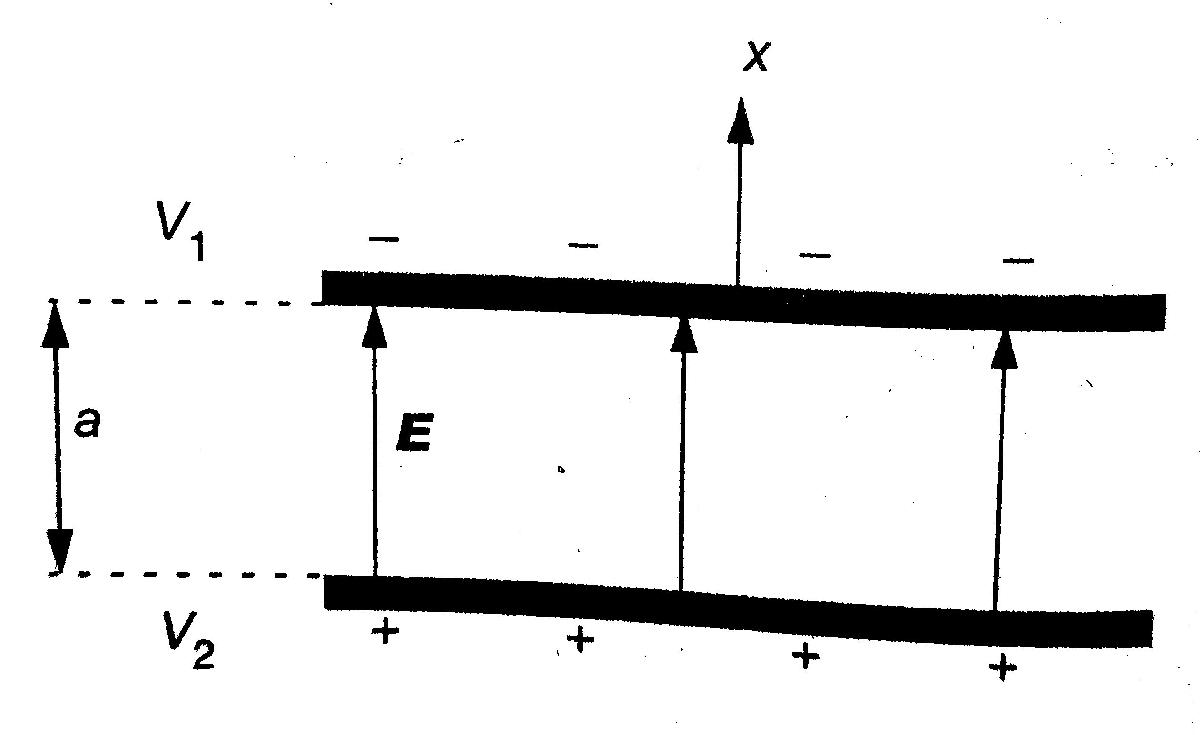


$$E=\frac{V_2 -V_1 }{a}\hat{x}$$


syms E V1 V2 a
E=[(V2-V1)/a,0,0]

$$E = \left(\begin{array}{ccc} -\frac{V_{1}-V_{2}}{a} & 0 & 0 \end{array}\right)$$

% a = расстояние между пластинами

#### Поле вокруг электрического точечного заряда и снаружи заряженной сферы

syms E epsilon0 Q r
E==1/(4*pi*epsilon0)*Q/r^2

$$ans = \text{E}=\frac{Q}{4\,\epsilon_{0}\,r^{2}\,\pi }$$

V==1/(4*pi*epsilon0)*Q/r

$$ans = V=\frac{Q}{4\,\epsilon_{0}\,r\,\pi }$$

% r = расстояние от центра распределения заряда

#### Поле внутри равномерно заряженного шара

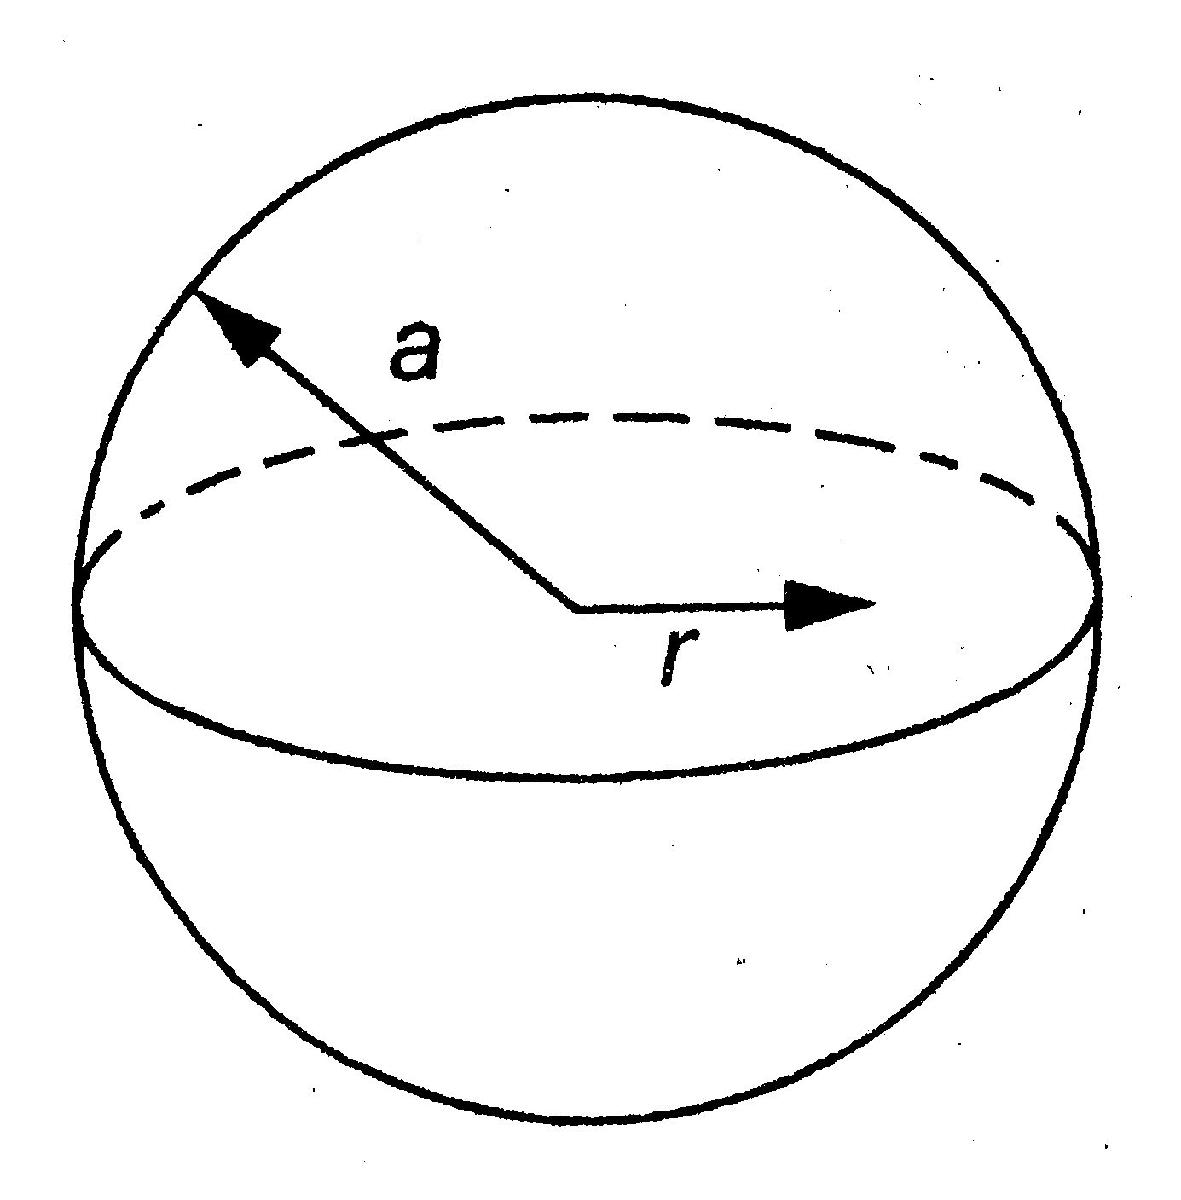

syms rho r epsilon0 Q a E_r
E_r==rho*r/(3*epsilon0)==Q*r/(4*pi*epsilon0*a^3)

$$ans = \left(E_{r}=\frac{r\,\rho }{3\,\epsilon_{0}}\right)=\frac{Q\,r}{4\,a^{3}\,\epsilon_{0}\,\pi }$$

% Q = полный заряд шара
% a = радиус шара

#### Поле на оси равномерно заряженного кольца

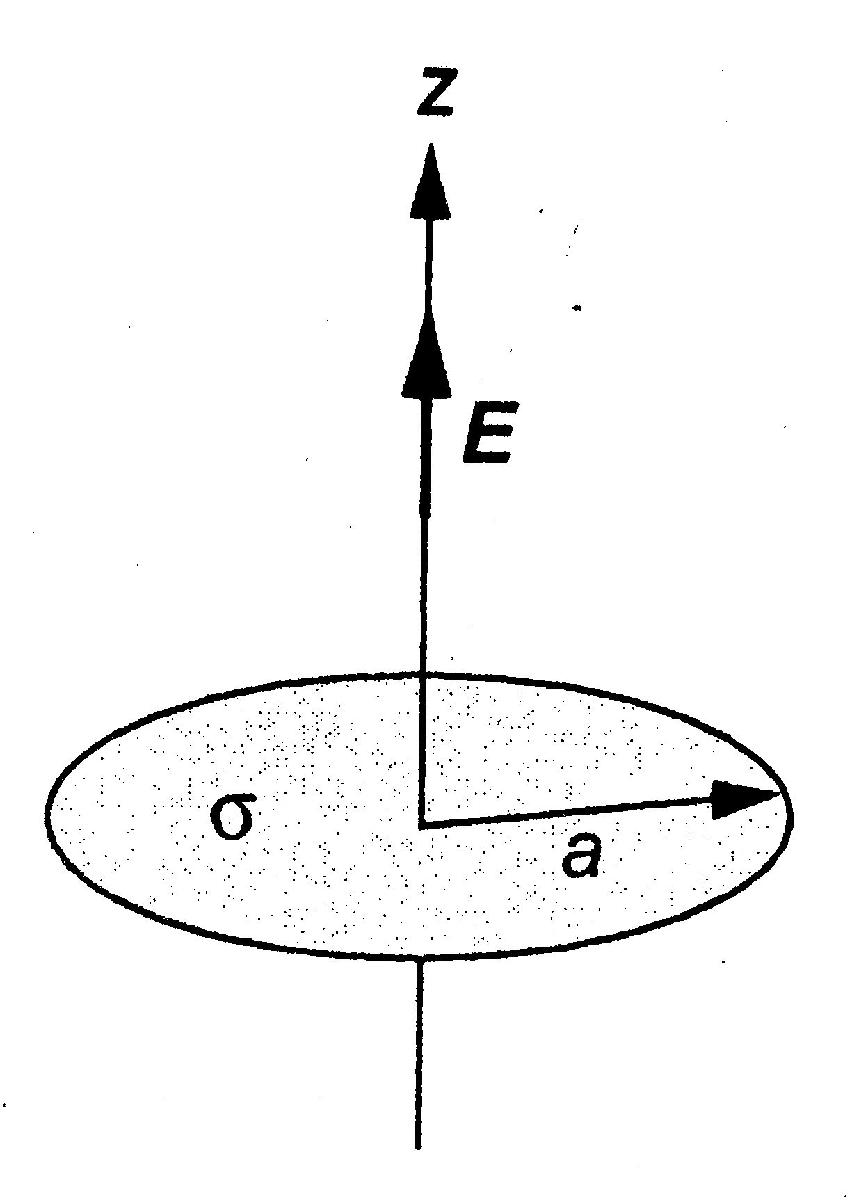

syms E_z sigma z 
E_z==sigma*z/(2*epsilon0)*(1/abs(z)-1/sqrt(z^2+a^2))

$$ans = E_{z}=\frac{\sigma \,z\,\left(\frac{1}{\left|z\right|}-\frac{1}{\sqrt{a^{2}+z^{2}}}\right)}{2\,\epsilon_{0}}$$

V==sigma/(2*epsilon0)*(sqrt(z^2+a^2)-abs(z))

$$ans = V=-\frac{\sigma \,\left(\left|z\right|-\sqrt{a^{2}+z^{2}}\right)}{2\,\epsilon_{0}}$$

% a = радиус кольца

Поверхностная плотность заряда

sigma==Q/(pi*a^2)

$$ans = \sigma =\frac{Q}{a^{2}\,\pi }$$

% Q = полный заряд диска

#### Поле бесконечно длинного проводника

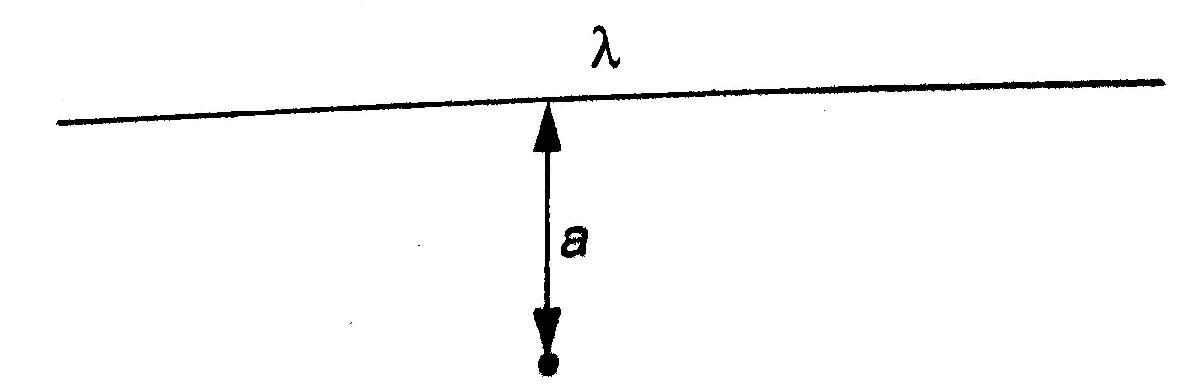

syms E lambda epsilon0 a a0
E==lambda/(2*pi*epsilon0*a)

$$ans = \text{E}=\frac{\lambda }{2\,a\,\epsilon_{0}\,\pi }$$

V=-lambda/(2*pi*epsilon0)*log(a/a0)

$$V = -\frac{\lambda \,\log\left(\frac{a}{a_{0}}\right)}{2\,\epsilon_{0}\,\pi }$$

% lambda = линейная плотность заряда
% a0 = расстояние от проводника, на котором V=0

#### [Уравнение Пуассона](https://ru.wikipedia.org/wiki/Уравнение_Пуассона)


$$\nabla^{2\;} V=-\frac{\rho }{\varepsilon_0 }$$


syms V rho epsilon0 nabla(x,n)
nabla(V,2)==-rho/epsilon0

$$ans = \mathrm{nabla}\left(V,2\right)=-\frac{\rho }{\epsilon_{0}}$$

% Delta(V) = nabla(V,2) = ∇^2(V)

#### [Теорема Гаусса](https://ru.wikipedia.org/wiki/Теорема_Гаусса) для потока вектора напряженности


$$\Phi_E =\oint \mathit{\mathbf{E}}\;\mathbf{dS}=\frac{Q}{\varepsilon_0 }$$


syms Phi_E E(S) Q
Phi_E==int(E,S)==Q/epsilon0

$$ans(S) = \left(\Phi_{E}=\int \text{E}\left(S\right)\mathrm{d}S\right)=\frac{Q}{\epsilon_{0}}$$

% Q = полный заряд внутри замкнутой поверхности S.

#### Альтернативная формулировка теоремы Гаусса для неполяризованного пространства


$$\mathrm{div}\;\mathit{\mathbf{E}}=\frac{\rho }{\varepsilon_0 }$$


syms E rho
div(E)==rho/epsilon0

$$ans = \mathrm{div}\left(\text{E}\right)=\frac{\rho }{\epsilon_{0}}$$

% div(E) = ∇E

#### Невихревое кулоновское поле


$$\mathrm{curl}\;\mathit{\mathbf{E}}=0$$


syms E
rot(E)==0

$$ans = \mathrm{rot}\left(\text{E}\right)=0$$

% rot(E) = ∇×E